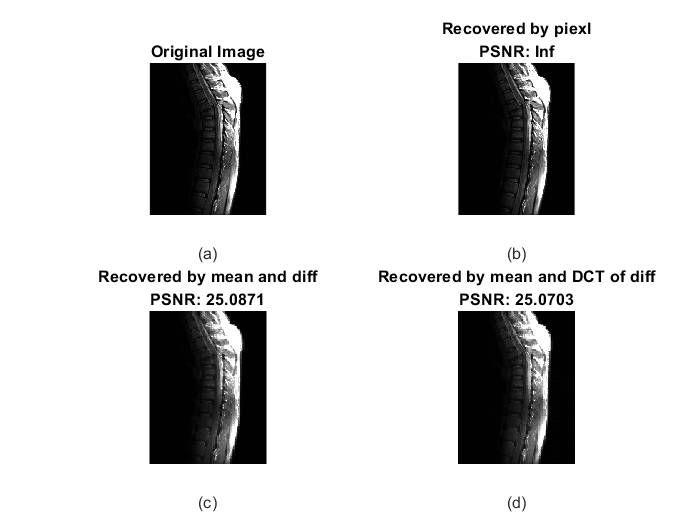

% Subplot 2*2
clear all;
close all;
clc;

% img_original = imread('cameraman.jpg');
img_original = imread('spine.jpg');
% img_original = imread('sar.gif');
% img_original = imread('circuit1.bmp');



% ------------First figure section
% % Read original image.
% figure(1);
% subplot(2,2,1);
% imshow(img_original);
% title('Original image');
% xlabel('(a)');
% hold on;
% % Show the mean image.
% fun = @(block_struct)mean2(block_struct.data) *...
%     ones(size(block_struct.data));
% mean_img_double = blockproc(img_original, [8 8], fun);
% subplot(2,2,2);
% imshow(uint8(mean_img_double));
% title('Mean image');
% xlabel('(b)');
% % Show the difference image.
% diff_img_double = double(img_original) - mean_img_double;
% diff_img_uint8 = uint8(diff_img_double);
% subplot(2,2,3);
% imshow(diff_img_uint8);
% title('Difference image');
% xlabel('(c)');
% % Show the DCT of the difference image.
% % DCT coefficients for diff image.
% fun_dct = @(block_struct)dct2(block_struct.data);
% dct_coefficient_diff =  blockproc(diff_img_double, [8 8], fun_dct);
% subplot(2,2,4);
% imshow(uint8(dct_coefficient_diff));
% title('DCT for the difference image');
% xlabel('(d)');
% hold off;



% ---------Second figure section
% Compare the compression result of different encode/decode pairs.
% Directly encode the image after quantization.
figure(2);
subplot(2,2,1);
imshow(img_original);
title('Original Image');
xlabel('(a)');
hold on;
% Recovered by method from task 1.
[zipped, info] = pixel_coder(img_original);
img_recovered_piexl = pixel_decoder(zipped, info);
subplot(2,2,2);
imshow(img_recovered_piexl);
psnr_piexl = psnr(img_recovered_piexl, img_original);
str = ['Recovered by piexl', newline, 'PSNR: ', num2str(psnr_piexl)];
title(str);
xlabel('(b)');
% Recovered by method from task 2.
[zipped, info] = diff_coder(img_original);
img_recovered_by_diff = diff_decoder(zipped, info);
subplot(2,2,3);
imshow(img_recovered_by_diff);
psnr_diff = psnr(img_recovered_by_diff, img_original);
str = ['Recovered by mean and diff',newline, 'PSNR: ', num2str(psnr_diff)];
title(str);
xlabel('(c)');
% Recovered by method from task 3.
[zipped, info] = jpeg_lite(img_original);
img_recovered_by_dct_diff = jpeg_lite_decoder(zipped, info);
subplot(2,2,4);
imshow(img_recovered_by_dct_diff);
psnr_dct_diff = psnr(img_recovered_by_dct_diff, img_original);
str = ['Recovered by mean and DCT of diff', newline, 'PSNR: ', num2str(psnr_dct_diff)];
title(str);
xlabel('(d)');

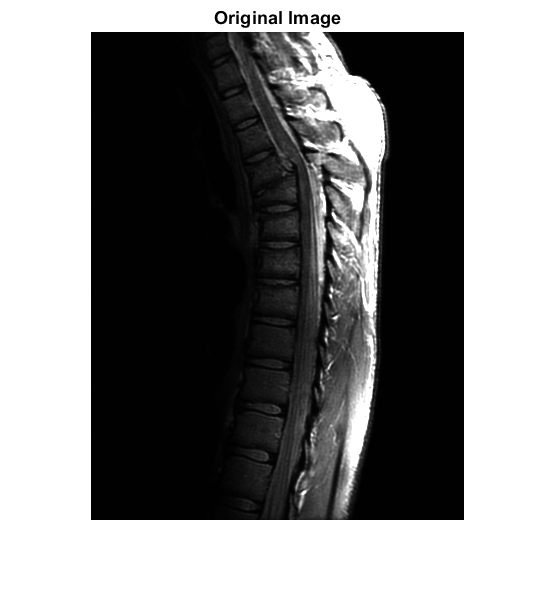

% One by one plot
clear all;
close all;
clc;


% img_original = imread('cameraman.jpg');
img_original = imread('spine.jpg');
% img_original = imread('sar.gif');
% img_original = imread('circuit1.bmp');

imshow(img_original);
title('Original Image');

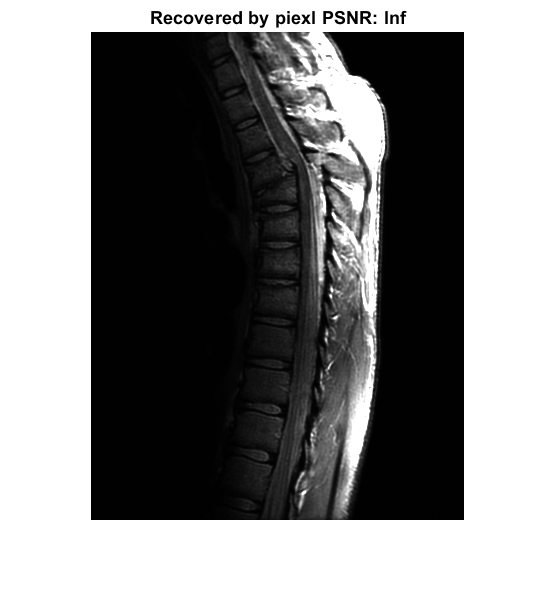

% xlabel('(a)');
% hold on;
% Recovered by method from task 1.
[zipped, info] = pixel_coder(img_original);
img_recovered_piexl = pixel_decoder(zipped, info);
% subplot(2,2,2);
imshow(img_recovered_piexl);
psnr_piexl = psnr(img_recovered_piexl, img_original);
str = ['Recovered by piexl ',  'PSNR: ', num2str(psnr_piexl)];
title(str);

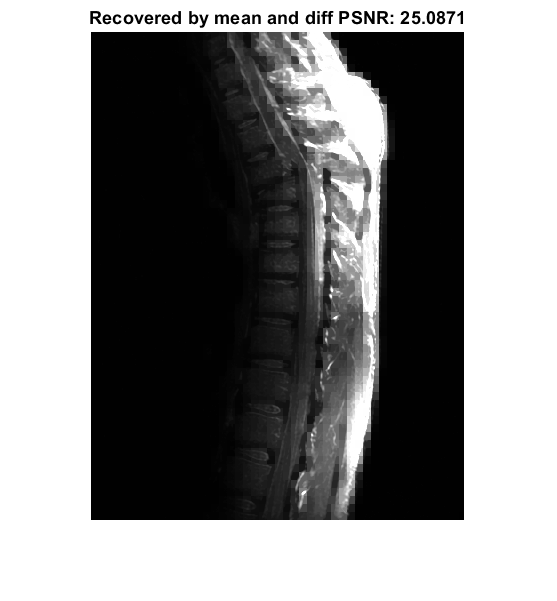

% xlabel('(b)');
% Recovered by method from task 2.
[zipped, info] = diff_coder(img_original);
img_recovered_by_diff = diff_decoder(zipped, info);
% subplot(2,2,3);
imshow(img_recovered_by_diff);
psnr_diff = psnr(img_recovered_by_diff, img_original);
str = ['Recovered by mean and diff ', 'PSNR: ', num2str(psnr_diff)];
title(str);

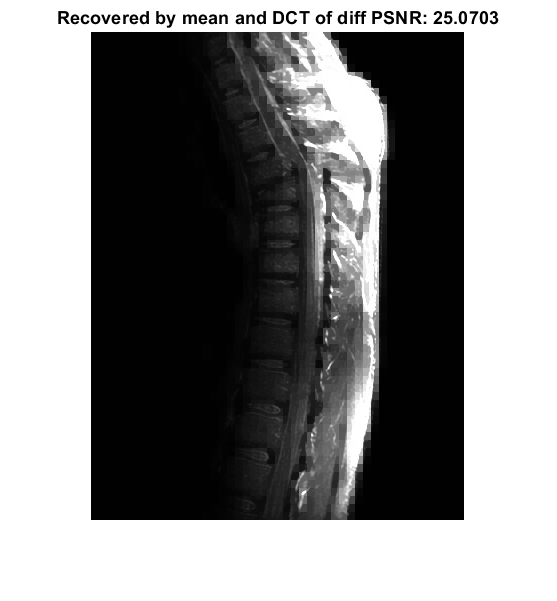

% xlabel('(c)');
% Recovered by method from task 3.
[zipped, info] = jpeg_lite(img_original);
img_recovered_by_dct_diff = jpeg_lite_decoder(zipped, info);
% subplot(2,2,4);
imshow(img_recovered_by_dct_diff);
psnr_dct_diff = psnr(img_recovered_by_dct_diff, img_original);
str = ['Recovered by mean and DCT of diff ', 'PSNR: ', num2str(psnr_dct_diff)];
title(str);

% xlabel('(d)');

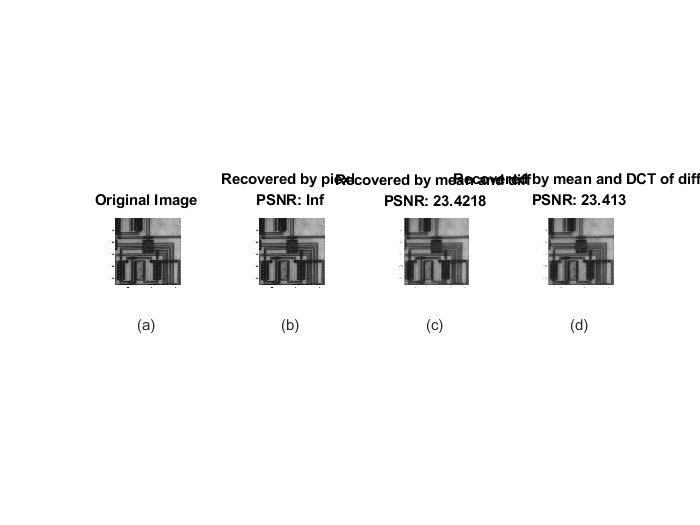

% Subplot 1*4
clear all;
close all;
clc;


% img_original = imread('cameraman.jpg');
% img_original = imread('spine.jpg');
% img_original = imread('sar.gif');
img_original = imread('circuit1.bmp');

figure(2);
subplot(1,4,1);
imshow(img_original);
title('Original Image');
xlabel('(a)');
hold on;
% Recovered by method from task 1.
[zipped, info] = pixel_coder(img_original);
img_recovered_piexl = pixel_decoder(zipped, info);
subplot(1,4,2);
imshow(img_recovered_piexl);
psnr_piexl = psnr(img_recovered_piexl, img_original);
str = ['Recovered by piexl ', newline, 'PSNR: ', num2str(psnr_piexl)];
title(str);
xlabel('(b)');
% Recovered by method from task 2.
[zipped, info] = diff_coder(img_original);
img_recovered_by_diff = diff_decoder(zipped, info);
subplot(1,4,3);
imshow(img_recovered_by_diff);
psnr_diff = psnr(img_recovered_by_diff, img_original);
str = ['Recovered by mean and diff ', newline,  'PSNR: ', num2str(psnr_diff)];
title(str);
xlabel('(c)');
% Recovered by method from task 3.
[zipped, info] = jpeg_lite(img_original);
img_recovered_by_dct_diff = jpeg_lite_decoder(zipped, info);
subplot(1,4,4);
imshow(img_recovered_by_dct_diff);
psnr_dct_diff = psnr(img_recovered_by_dct_diff, img_original);
str = ['Recovered by mean and DCT of diff ', newline, 'PSNR: ', num2str(psnr_dct_diff)];
title(str);
xlabel('(d)');